% Load the carsmall data set. Consider Horsepower and Weight as predictor variables.
% 因变量MPG意思是miles per gallon 每加仑英里数，反映发动机的效率

load carsmall;
X = [Weight Horsepower];
varNames = {'Weight' 'Horsepower'};
% Grow a regression tree using the entire data set. View the tree.

Mdl = fitrtree(X,MPG,'PredictorNames',varNames)

Mdl =   RegressionTree
           PredictorNames: {'Weight'  'Horsepower'}
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 94


  Properties, Methods


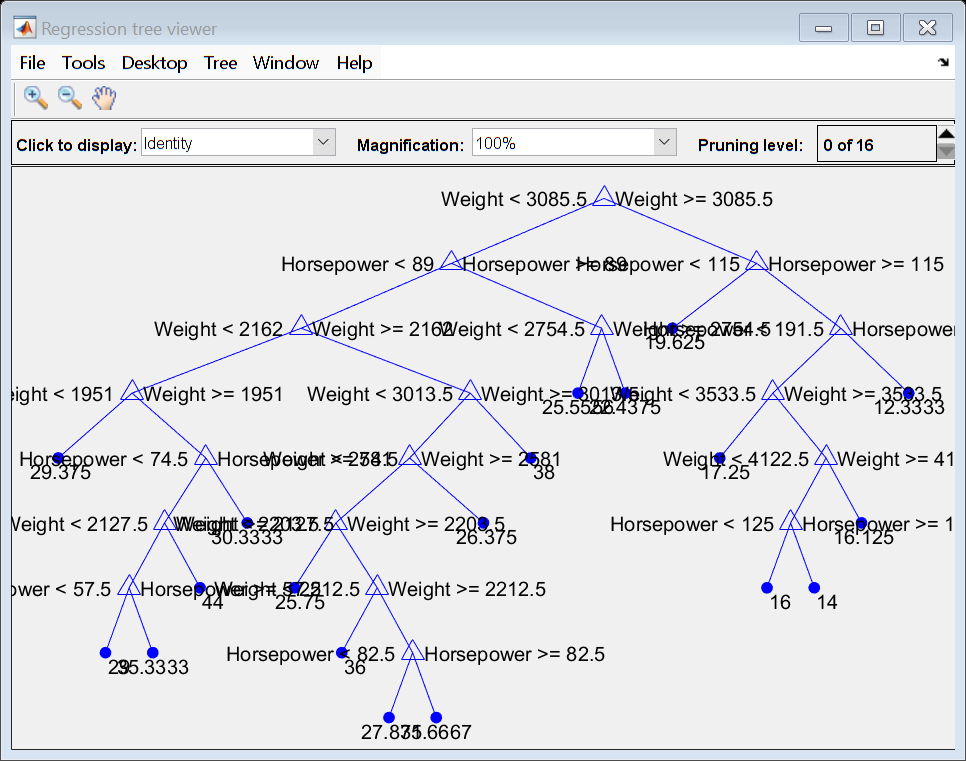


view(Mdl,'Mode','graph');

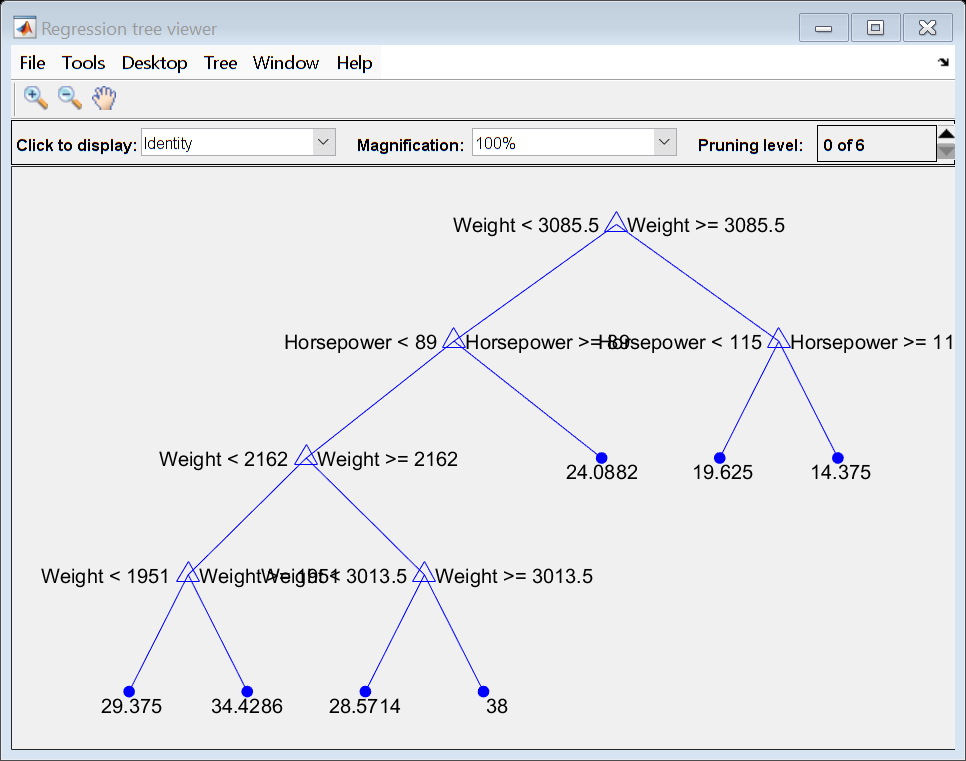

% Figure Regression tree viewer contains an axes object and other objects of 
% type uimenu, uicontrol. The axes object contains 60 objects of type line, text.

% The regression tree has 16 pruning levels.

% Prune the regression tree to pruning-level 10. View the pruned tree.

MdlPruned = prune(Mdl,'Level',10);
view(MdlPruned,'Mode','graph');

% Figure Regression tree viewer contains an axes object and other objects of type uimenu, uicontrol. The axes object contains 24 objects of type line, text.
% 
% The pruned tree has six pruning levels.
% 
% Alternatively, you can use the pruning-level field in the Regression tree viewer to prune the tree.